clear; clc;
close all;

%% Text Size
set(0,'DefaultAxesFontsize',6);
set(0,'DefaultTextFontsize',6);

%% Text Fonts
set(0,'DefaultTextFontname','Arial');
set(0,'DefaultAxesFontname','Arial');

figsize = [10 15 5.3 3.5];
figpos = [0.18 0.25 0.69 0.65];
lw = 0.8;

% pclist = [];
% stmlist = [];
% lorenzerrorlist = [];
% 
% Nrlist = [10 20 50 500];
% SRlist = [1.7 1.1 1.1 1.1];
% 
% for k = 1:4 % 1:4
% Nr = Nrlist(k);
% SR = SRlist(k);
% 
% for No = 1:100 % 1:100
% 
% clear('edtwlorenz', 'pc_allcoeff', 'stm_allcoeff');
% 
% filename = ['esnseed\esn_Nr' num2str(Nr) 'SR' num2str(SR*10) 'No' num2str(No) '.mat'];
% load(filename, 'edtwlorenz', 'pc_allcoeff', 'stm_allcoeff');
% 
% pclist = [pclist; pc_allcoeff];
% stmlist = [stmlist; stm_allcoeff];
% lorenzerrorlist = [lorenzerrorlist; edtwlorenz];
% 
% end
% end
% 
% save('data\fig5_controlerrordatadtw.mat', 'pclist', 'stmlist', 'lorenzerrorlist');

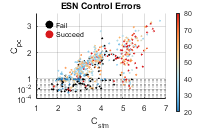

load('data\fig5_controlerrordatadtw.mat');

kh = find(pclist + stmlist > 7);
kl = find(pclist + stmlist <= 7);
khsucc = find(pclist + stmlist > 7 & lorenzerrorlist<=1000);
khfr = (size(kh) - size(khsucc))/size(kh);
khme = mean(lorenzerrorlist(khsucc));
klsucc = find(pclist + stmlist <= 7 & lorenzerrorlist<=1000);
klfr = (size(kl) - size(klsucc))/size(kl);
klme = mean(lorenzerrorlist(klsucc));

scattersize = 3;
[lorenzerrorlist, idx] = sort(lorenzerrorlist, 'descend');
pclist = pclist(idx);
stmlist = stmlist(idx);

figure('Color',[1 1 1]);
set(gcf,'unit','centimeters','position',figsize);
set(gca,'Position', figpos);
set(gcf,'Visible','on');

k1 = find((isnan(lorenzerrorlist) | lorenzerrorlist>1000) & pclist>=1);
k2 = find(lorenzerrorlist<=1000 & pclist>=1);
k3 = find((isnan(lorenzerrorlist) | lorenzerrorlist>1000) & pclist<1);
k4 = find(lorenzerrorlist<=1000 & pclist<1);

ax1 = subplot(211);
s11 = scatter(stmlist(k1), pclist(k1), [], [0 0 0], 'filled', 'SizeData', scattersize);
% leg = legend(s11, 'Fail');
% leg.Box = "off";
% leg.ItemTokenSize = [15 15];
hold on;
s12 = scatter(stmlist(k2), pclist(k2), [], lorenzerrorlist(k2), 'filled', 'SizeData', scattersize);
leg = legend('Fail', 'Succeed');
leg.Box = "off";
leg.ItemTokenSize = [5 15];
leg.Location = 'NorthWest';
% s2.MarkerFaceAlpha = 0.7;
clim([0 80]);
ylabel('C_{pc}');
title('ESN Control Errors');

ax2 = subplot(212);
s21 = scatter(stmlist(k3), pclist(k3), [], [0 0 0], 'filled', 'SizeData', scattersize);
hold on;
s22 = scatter(stmlist(k4), pclist(k4), [], lorenzerrorlist(k4), 'filled', 'SizeData', scattersize);
% s2.MarkerFaceAlpha = 0.7;
clim([20 80]);

% [0.18 0.25 0.69 0.65];
set(ax1,'position',[0.18 0.40 0.65 0.50]);
set(ax1,'ylim',[1 3.5],'YTick',1:3);
set(ax2,'position',[0.18 0.25 0.65 0.15]);
set(ax2,'yscale','log','ylim',[1e-4 1],'YTick',[1e-4 1e-2]);
set([ax1 ax2],'xlim',[1 7],'xtick',1:7,'box','off');
ax1.XAxis.Visible = 'off';

% colormap(flipud(hot));
% colormap(flipud(summer));
colormap(flipud(othercolor('RdYlBu4')));
cb = colorbar();
cb.Position = [0.88, 0.15, 0.02, 0.75];
grid(ax1,'on');
grid(ax2,'on');
uistack(ax2,'top');
xlabel('C_{stm}');